# Period 25: Item 6 - Equalize Image 

### ### Agam Goyal ###

## Prepare Workspace

clc
close all
clear

load('Per25dat.mat')

## One-dimensional equalizer

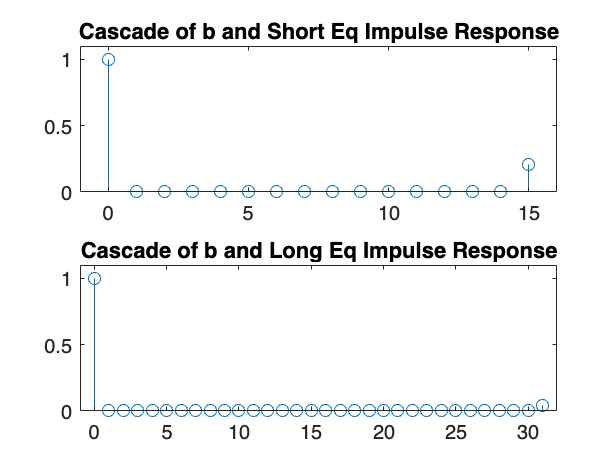

b = [1 0.9]; % Impulse response of distortion

d1 = (-0.9).^[0:14]; % Impulse response of short equalizer
d2 = (-0.9).^[0:30]; % Impulse response of long equalizer

hnet1 = conv(b,d1); % Imp resp of cascade of distortion and short eq
hnet2 = conv(b,d2); % Imp resp of cascade of distortion and long eq

figure
subplot(211)
stem(0:length(hnet1)-1,hnet1)
title('Cascade of b and Short Eq Impulse Response')
xlim([-1, length(hnet1)])
ylim([0, 1.1])

subplot(212)
stem(0:length(hnet2)-1,hnet2)
title('Cascade of b and Long Eq Impulse Response')
xlim([-1, length(hnet2)])
ylim([0, 1.1])

**Insert Notes Here (For Personal Reference Only): **

## Filter image

Define point-spread function for distortion based on applying b to rows and columns of the image

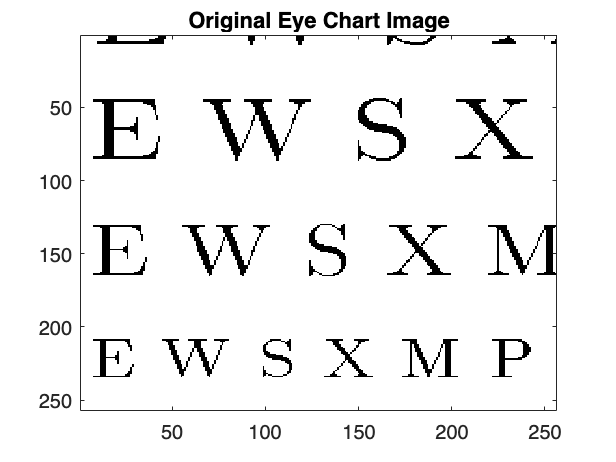

h_psf = b*b'; %<- Uncomment and complete

figure
imagesc(echart)
colormap(gray)
title('Original Eye Chart Image')

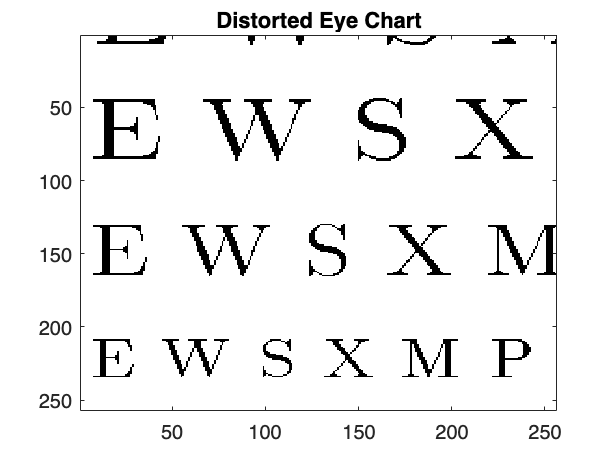


% Apply point-spread function to filter image using 2D convolution
echartma = conv2(echart, h_psf); %<- Uncomment and complete

figure
imagesc(echartma)
colormap(gray)
title('Distorted Eye Chart')

## Apply Equalizer to Distorted Eye Chart

Define equalizer point-spread functions by applying short and long equalizer impluse responses (d1 and d2) across the rows and columns

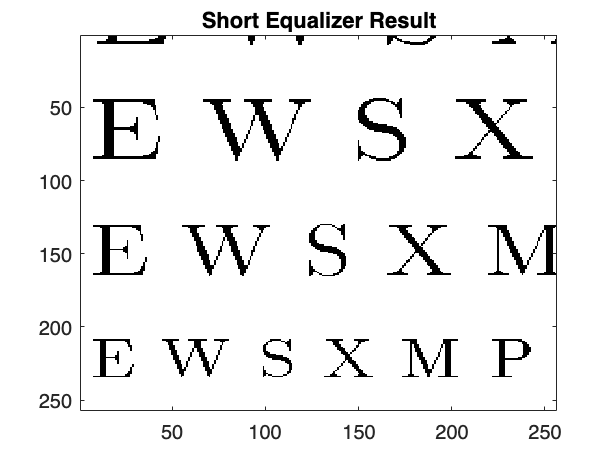

% short equalizer psf
heq1_psf = d1*d1'; %<- Uncomment and complete

% long equalizer psf
heq2_psf = d2*d2';  %<- Uncomment and complete

% Apply short equalizer to filter distorted image
echarteq1 = conv2(echartma,heq1_psf);  %<- Uncomment and complete

figure
imagesc(echarteq1)
colormap(gray)
title('Short Equalizer Result')

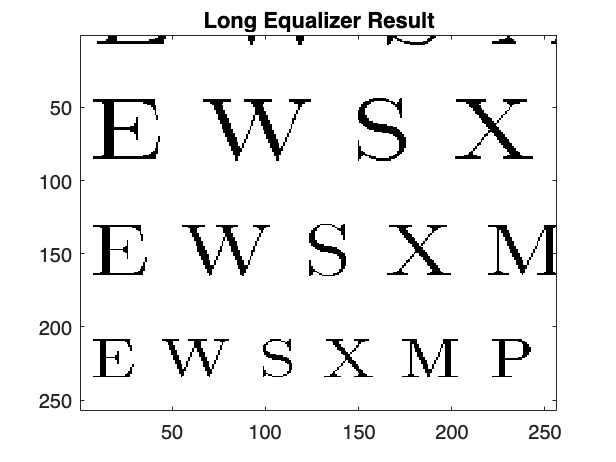


% Apply long equalizer to filter distorted image
echarteq2 = conv2(echartma,heq2_psf);  %<- Uncomment and complete

figure
imagesc(echarteq2)
colormap(gray)
title('Long Equalizer Result')